# Virtual Species Hyperspace Experimentation

The objetive of this livescript is to evaluate the performance of Virtual Species methods in the hyperspace $\theta_M$.

## Beta Deformations

### 1. Preparing environment

#### 1.1 Clear command window, workspace variables, and close all figures

clear; clc; close all;

#### 1.2. Set the path to the folder containing the layer data

layerfolder = '../VirtualSpeciesGeneration/data/Capas_Colombia_30S/';

#### 1.3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 11.645743 seconds.


rows = Layers.Dimensions(1);
layer_num = Layers.Dimensions(2);

### Niche generation

#### 2. Generate initial point for niche generation using Beta Deformations.

- To execute InitialPoint, there is one required input and six additional optional inputs.

- Use 'beta' as the method.

- Set plotting to 'false'

- Set random_point to 'false'

- Choose point

 InitialPoint = InitialPoint(layers, method, plotting, random_point, point, coeff, deformations_limit)

middle_point = repmat(rows/2, layer_num,1);
InfoInitialPoint = InitialPoint(Layers,'beta', false, false, middle_point);

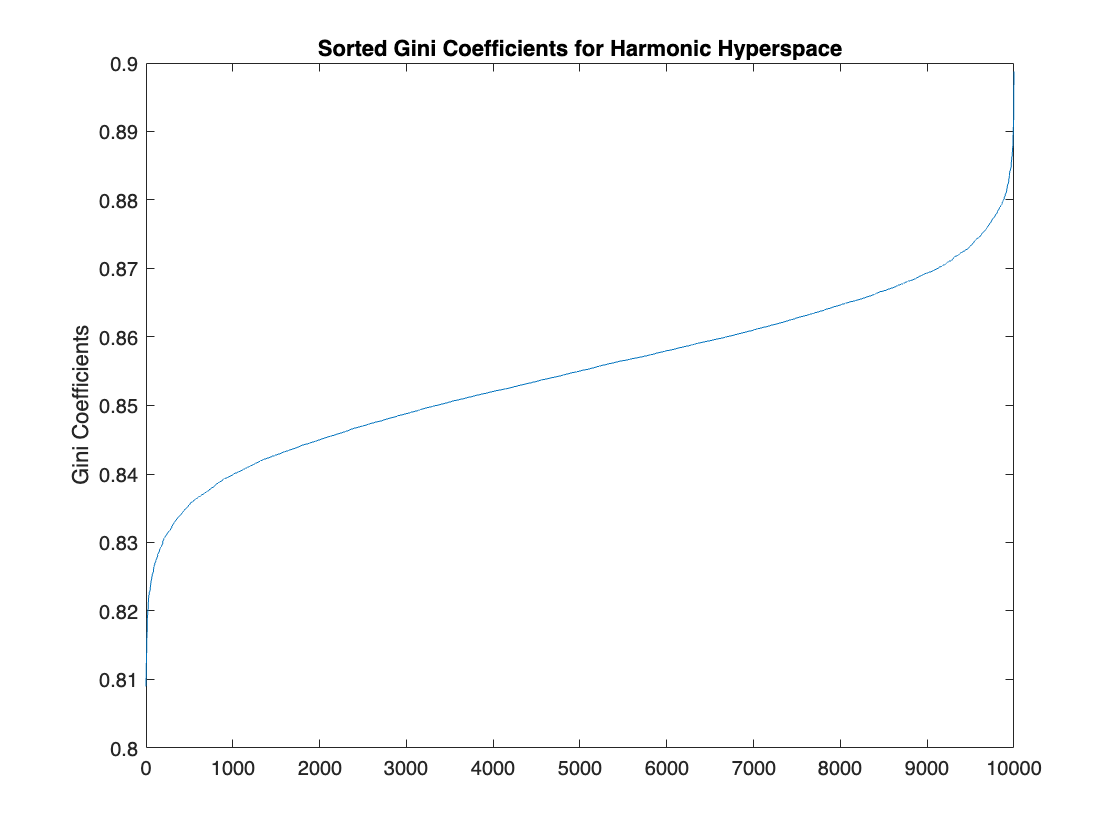

InfoInitialPoint = InitialPoint(Layers,'harmonic', true);

middle_point = repmat(0.5, layer_num,1);
N = 200;
BetaHyperspace = cell(1, N);
for Ni=1:N
    BetaHyperspace{Ni} = InitialPoint(Layers,'beta', false, false, middle_point).NormDistance;
end

nonNaNCount = sum(~isnan(BetaHyperspace{1}));
% Preallocate an array for storing Gini indexes
betaGiniCoefficients = zeros(1, nonNaNCount);

% Loop through each position in the cell array
for i = 1:nonNaNCount
    values = cellfun(@(x) x(i), BetaHyperspace);
    % Check if any element in the array is NaN
    if any(isnan(values))
        % Skip this position if NaN is present
        continue;
    end
    
    % Calculate Gini index for the array at position i
    betaGiniCoefficients(i) = calculateGini(values);
end
mean(betaGiniCoefficients)

ans = 0.8809

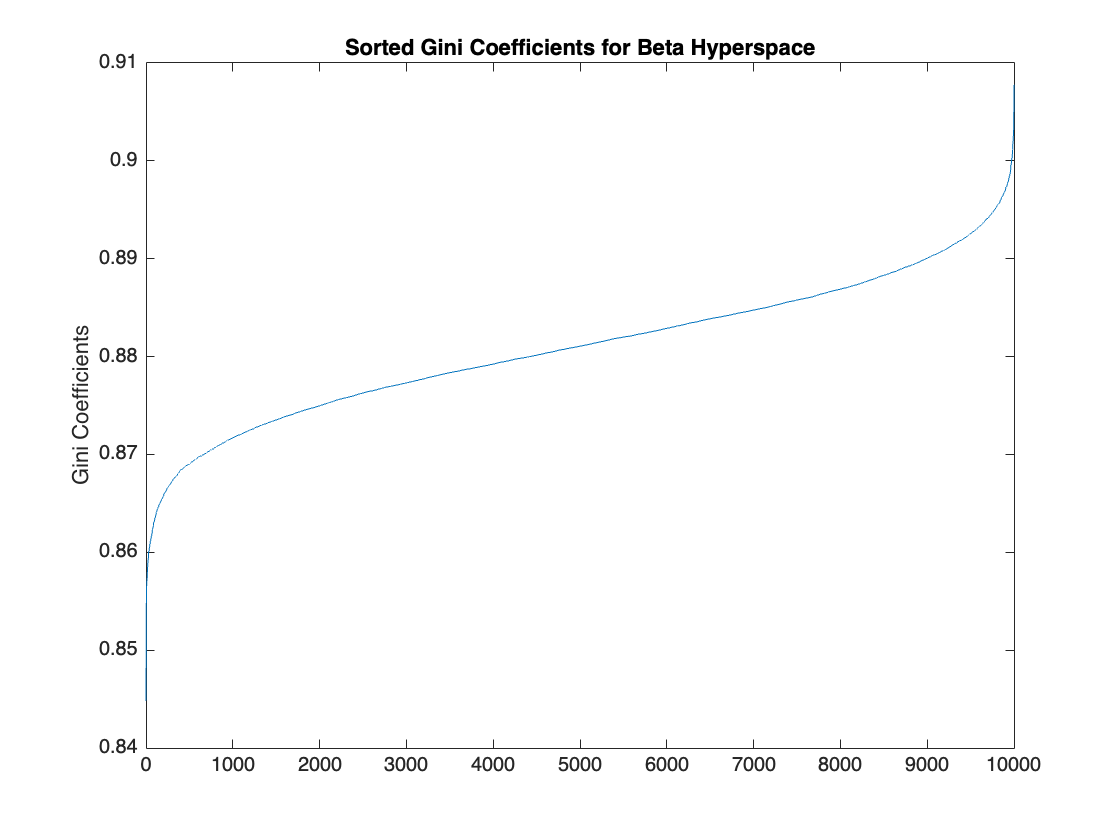

plot(sort(betaGiniCoefficients))
ylabel('Gini Coefficients')
title('Sorted Gini Coefficients for Beta Hyperspace')

N = 200;
middle_point = repmat(0.5, layer_num,1);
CoeffHyperspace = cell(1, N);
for Ni=1:N
    CoeffHyperspace{Ni} = InitialPoint(Layers,'coeff', false, false, middle_point).NormDistance;
end

nonNaNCount = sum(~isnan(CoeffHyperspace{1}));
% Preallocate an array for storing Gini indexes
coeffGiniCoefficients = zeros(1, nonNaNCount);

% Loop through each position in the cell array
for i = 1:nonNaNCount
    values = cellfun(@(x) x(i), CoeffHyperspace);
    % Check if any element in the array is NaN
    if any(isnan(values))
        % Skip this position if NaN is present
        continue;
    end
    
    % Calculate Gini index for the array at position i
    coeffGiniCoefficients(i) = calculateGini(values);
end
mean(coeffGiniCoefficients)

ans = 0.8785

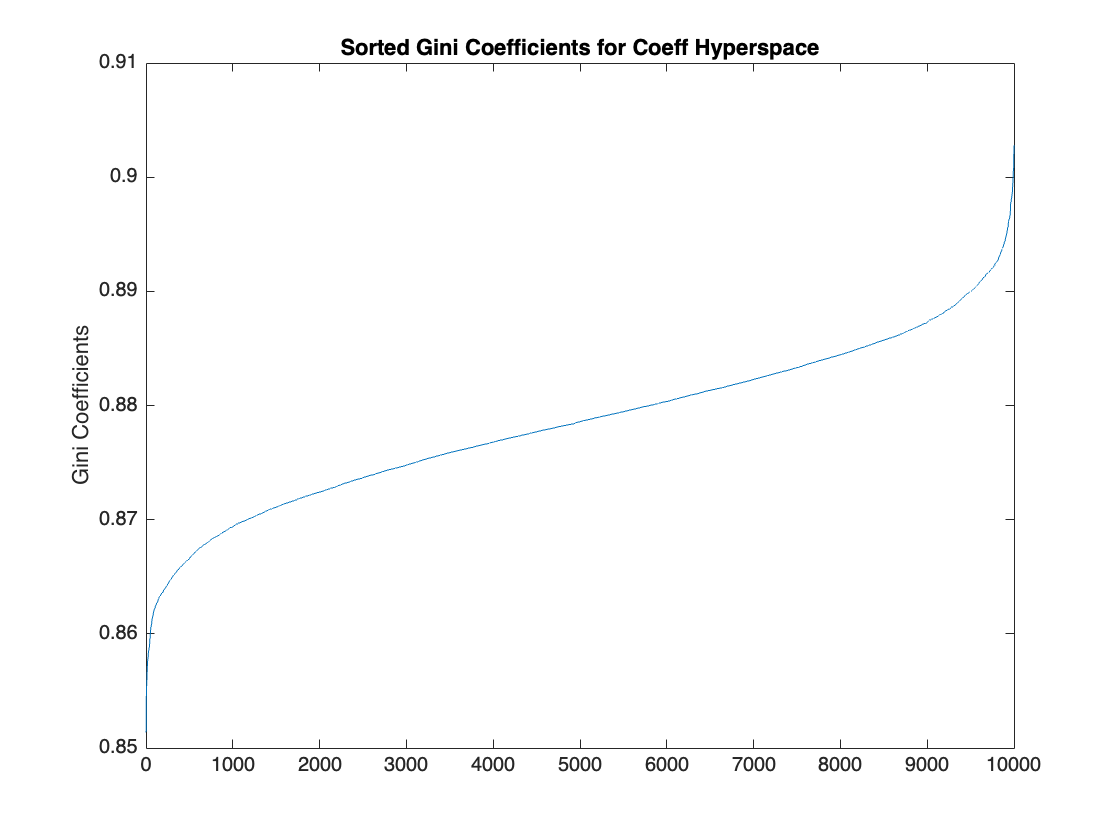

plot(sort(coeffGiniCoefficients))
ylabel('Gini Coefficients')
title('Sorted Gini Coefficients for Coeff Hyperspace')

N = 100;
middle_point = ones(layer_num)*0.5;
HarmonicHyperspace = cell(1, N);
for Ni=1:N
    HarmonicHyperspace{Ni} = InitialPoint(Layers,'harmonic', false, false, middle_point).NormDistance;
end

nonNaNCount = sum(~isnan(HarmonicHyperspace{1}));
% Preallocate an array for storing Gini indexes
harmonicGiniCoefficients = zeros(1, nonNaNCount);

% Loop through each position in the cell array
for i = 1:nonNaNCount
    values = cellfun(@(x) x(i), HarmonicHyperspace);
    % Check if any element in the array is NaN
    if any(isnan(values))
        % Skip this position if NaN is present
        continue;
    end
    
    % Calculate Gini index for the array at position i
    harmonicGiniCoefficients(i) = calculateGini(values);
end
mean(harmonicGiniCoefficients)

ans = 0.9148

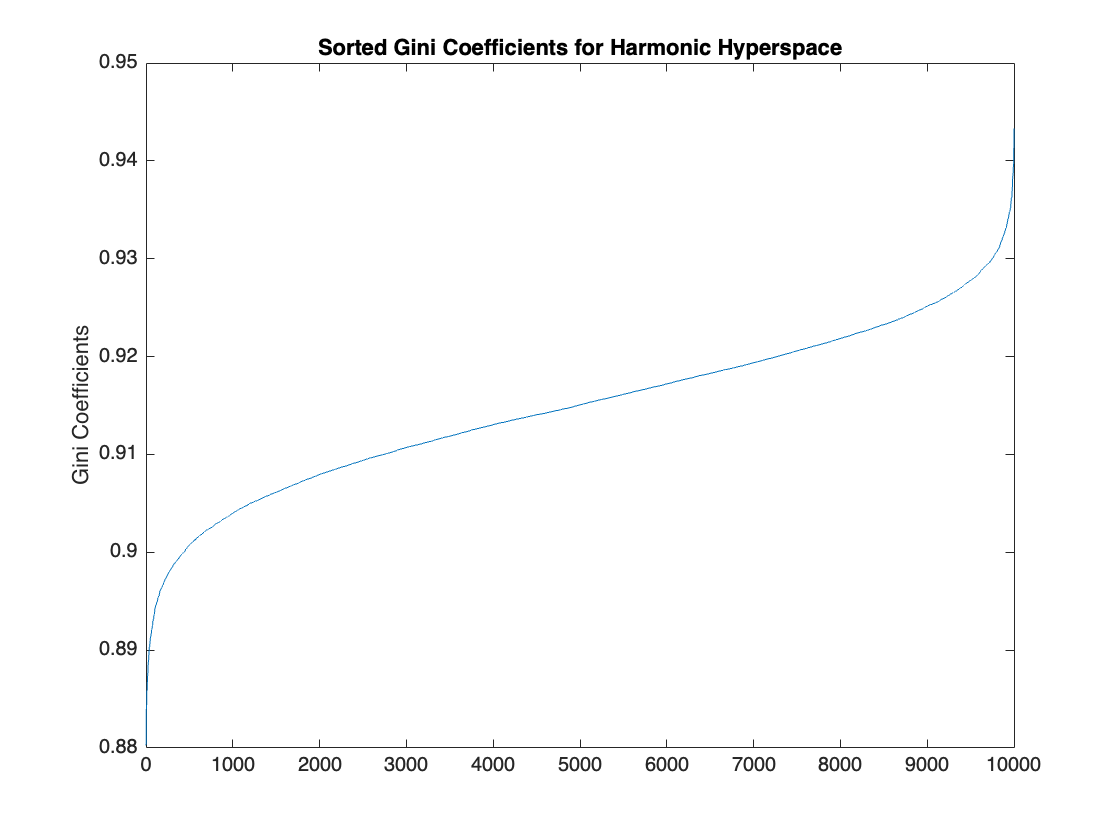

plot(sort(harmonicGiniCoefficients))
ylabel('Gini Coefficients')
title('Sorted Gini Coefficients for Harmonic Hyperspace')


function giniCoefficient = calculateGini(array)
    % Sort the array in ascending order
    sortedArray = sort(array);
    
    % Calculate cumulative proportions
    cumulativePopulation = cumsum(sortedArray) / sum(sortedArray);
    
    % Calculate Lorenz curve coordinates
    lorenzCurveX = (1:length(sortedArray)) / length(sortedArray);
    lorenzCurveY = cumulativePopulation;
    
    % Calculate area under the Lorenz curve (A)
    areaA = trapz(lorenzCurveX, lorenzCurveY);
    
    % Calculate area under the line of equality (B)
    areaB = 0.5 - areaA;
    
    % Calculate Gini coefficient
    giniCoefficient = areaA / (areaA + areaB);
end